# Question 6

clear
clc
close all

PICTURE

load res_tf.mat
load r3r4.mat

addpath('./Data')
addpath('./Models')

load('ECP_values.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                     % Threshold angular velocity rad/s

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];            % Initial conditions
T_s = 0.004;                    % Sampling period
sigma_meas = 0.0093*eye(3);     % Measurements covariance matrix

% Load data
load ECP502Data.mat



## System

A = [0, 1, 0, 0, 0, 0; 
    -k_1/J_1, -b_1/J_1, k_1/J_1, 0, 0, 0; 
    0,0,0, 1,0,0; 
    k_1/J_2, 0, -(k_1 + k_2)/J_2, -b_2/J_2, k_2/J_2, 0; 
    0,0,0,0,0,1; 
    0,0, k_2/J_3, 0, -k_2/J_3, -b_3/J_3];

B = [0,0;
    1/J_1, 0; 
    0,0; 
    0,1/J_2; 
    zeros(2)];

C = [1, zeros(1,5); 0,0,1,zeros(1,3); zeros(1,4), 1, 0]; 
D = zeros(3,2); 
Ex = [0; -1/J_1; zeros(4,1)]; 
Ey = zeros(3,1);


## Question 1

## Question 2

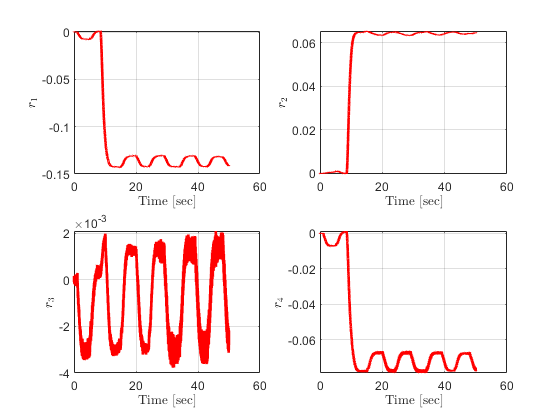

% Inputs
U = [t, y_meas, u_1, u_2];

% Tuning params
P_F = 0.0001; % false alarm probability
P_M = 0.01; % missed detection probability
h = log((1-P_M)/P_F); % threshold
M = 37; % window size


SIM_TIME = 50;
STEP_SIZE = 0.001;
t = 0:STEP_SIZE:SIM_TIME;
n_t = length(t);



% Simulation
out = sim('q6_TDO.slx', SIM_TIME, [], U);

% % Residuals
r = out.r.Data;
r1 = r(:,1);
r2 = r(:,2);
r3 = r(:,3);
r4 = r(:,4);
t_d = out.r.Time;

g = out.g.Data;

% Plots
figure(1)
subplot(2,2,1)
plot(t_d, r1, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_1$', "interpreter", "latex")

subplot(2,2,2)
plot(t_d, r2, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_2$', "interpreter", "latex")

subplot(2,2,3)
plot(t_d, r3, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_3$', "interpreter", "latex")

subplot(2,2,4)
plot(t_d, r4, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$r_4$', "interpreter", "latex")

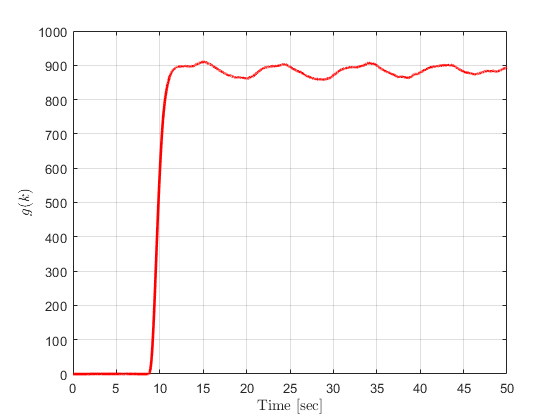



figure(2)
plot(t_d, g, 'r', 'LineWidth', 2)
grid on
xlabel('Time [sec]', "interpreter", "latex")
ylabel('$g(k)$', "interpreter", "latex")